# Thermophysical Property Prediction

Empirical regression has limitations, especially when predictions are requested outside of the training region. Physics-based information can overcome this limitation by including fundamental engineering knowledge such as constraints during the training process. Constraints can be important physics-based information to improve machine learned predictions. Constraints are demonstrated on linear regression with sample data. The purpose of this [Thermophysical Property Case Study](https://apmonitor.com/pds/index.php/Main/ThermophysicalProperties) is to evaluate the performance of a neural network with and without constraints for thermophysical property predictions.

## Linear Regression with and without Constraints

Below is an example of linear regression with and without a lower bound constraint on a parameter. In this case, the constraint is on the slope (a≥0).

% Define Data
x = rand([1 100]) + linspace(0,100);
y = rand([1 100]) - 2*linspace(0,1);

% Linear regression model (unconstrained)
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      0.54056      0.053755     10.056    9.1504e-17
    x1             -0.020587    0.00092179    -22.334    3.1409e-40


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.269
R-squared: 0.836,  Adjusted R-Squared: 0.834
F-statistic vs. constant model: 499, p-value = 3.14e-40

y_predicted = predict(model, x')';

% Make a constrained model (slope >= 0)
constrainedModel = @(var, x)var(1)*x + var(2); % Linear model
vars = lsqcurvefit(constrainedModel, [1,1], x, y, [0,-inf], [inf,inf]); % Fit with positive slope


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


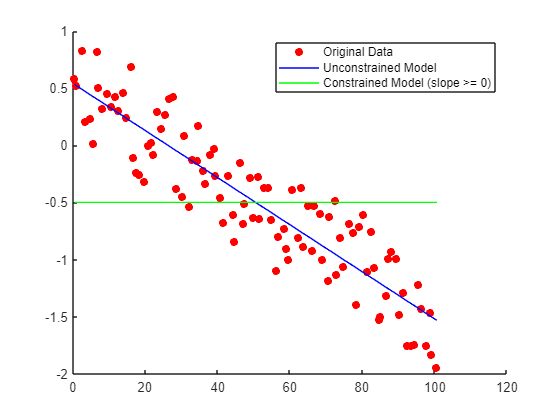


% Plot results
scatter(x,y,'r','filled')
hold on
plot(x,y_predicted, 'b')
plot(x, vars(1)*x + vars(2), 'g')
legend({'Original Data' 'Unconstrained Model' 'Constrained Model (slope >= 0)'})
hold off

The constrained model was forced to keep a positive slope which in this case didn't match the data well. Using real physics models as constraints can help match a fit to data better or discover problems with the model or with the data collection. In other cases using constraints can help the model to fit the data more accurately. 

## Predict Thermophysical Properties

**Background**: Parachor values are a factor in the prediction of several thermophysical properties such as surface tension and thermal conductivity. The parachor value (P) is used to predict surface tension with the difference between the density of saturated liquid ρL and saturated vapor ρV at the temperature of interest.


$$\sigma ={\left(P\left(\rho L-\rho v\right)\right)}^4$$


Surface tension and thermal conductivity are two specific properties that need improved predictions. A more accurate predictor of the parachor value (P) is an important step to improve those thermophysical properties. Most deep learning methods use a limited set of activation functions (ReLU, sigmoid, tanh, and linear) and perform unconstrained regression to minimize a loss function. The purpose of this case study is to explore the addition of physics-based information in the fitting process. This may include the use of new types of activation functions or constraints on the adjustable weights. The data for this case study is from Gharagheizi, et. al. (2011) who explored deep learning (a multi-layered neural network) to improve parachor predictions for 277 compounds from 40 functional groups.

- Name: The common chemical name

- Formula: Chemical formula of the compound

- CASN: Chemical Abstracts Service Registry Number

- Family: Chemical family of the compound

- Parachor: Estimate of parachor value

- Grp1-Grp40: Number of functional groups in the compound

**Objective**: Develop a prediction of the parachar from the chemical compound data set. Report the correlation coefficient (R2) for predicting Parachor in the test set. Randomly select values that split the data into a train (80%) and test (20%) set (Note: in the case of the following code, we select the index 205 arbitraraily to split the data, but other values can be used if desired). Use Linear Regression and Neural Network (Deep Learning) with constraints. The solutions for regression without constraints or feature engineering are provided in this notebook. For the constrained cases, enforce a positive parachor contribution for each group. Discuss the performance of each on the train and test sets. Submit source code and a summary memo (max 2 pages) of your results.

**Load Data**

[Chemical Compound Data Set](http://apmonitor.com/pds/uploads/Main/thermo.txt)

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt'

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt'

**Linear Regression without Constraints**

data = readtable(url, 'VariableNamingRule', 'preserve')

data = 227×45 table
              Name               Formula          CASN                   Family               Parachor    Grp1    Grp2    Grp3    Grp4    Grp5    Grp6    Grp7    Grp8    Grp9    Grp10    Grp11    Grp12    Grp13    Grp14    Grp15    Grp16    Grp17    Grp18    Grp19    Grp20    Grp21    Grp22    Grp23    Grp24    Grp25    Grp26    Grp27    Grp28    Grp29    Grp30    Grp31

functional_group_data = data(:, 6:45); % Isolate functional group data
data_train = table2array(functional_group_data(1:205, :)); % Split functional group data into a training set
data_validate = table2array(functional_group_data(206:end, :)); % Split functional group data into a validation set
p_train = table2array(data(1:205, 5)); % Split the parachor values into a training set 
p_validate = table2array(data(206:end, 5)); % Split the parachor values into a validation set 

% Perform linear regression
model = fitlm(data_train,p_train);

% Predict parachor values
p_predicted_train = predict(model, data_train);
p_predicted_validate = predict(model, data_validate);

% Get MSE values
squared_errors1 = abs(p_train-p_predicted_train);
for i=1:size(p_train)
    squared_errors1(i) = squared_errors1(i) / p_train(i); 

end
sum(squared_errors1)

ans = 8.2523

squared_errors = sum(squared_errors1, 'all') / 205

squared_errors = 0.0403

mse_lin_train = squared_errors;
fprintf("Train MSE: %.3f", squared_errors)

Train MSE: 0.040


squared_errors = (p_validate-p_predicted_validate).^2;
mse_lin_val = mean(squared_errors);
fprintf("Validation MSE: %.3f", mse_lin_val)

Validation MSE: 10169.280

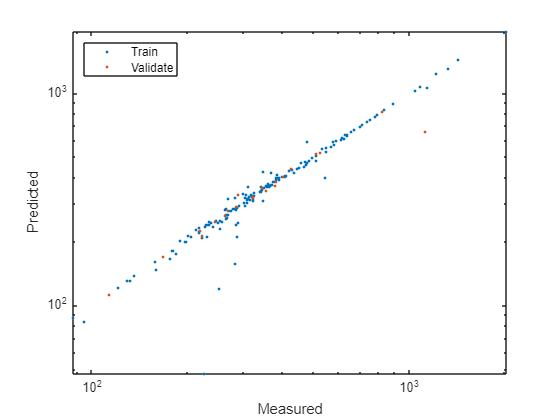


% Graph
figure;
loglog(p_train, p_predicted_train, '.', p_validate, p_predicted_validate, '.');
xlabel('Measured');
ylabel('Predicted');
legend('Train', 'Validate', 'Location', 'northwest');

## Neural Network (Deep Learning) without Constraints

Note: For more information for interactive approaches to designing Neural Networks like the following, refer back to the Neural Network Regressor module

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:21 |         1.13 |          0.6 |          0.0010 |
|      50 |          50 |       00:00:27 |         0.20 |      1.9e-02 |          0.0010 |
|     100 |         100 |       00:00:29 |         0.13 |      8.4e-03 |          0.0010 |
|     150 |         150 |       00:00:31 |         0.11 |      5.8e-03 |          0.0010 |
|     200 |         200 |       00:00:33 |         0.09 |      4.4e-03 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


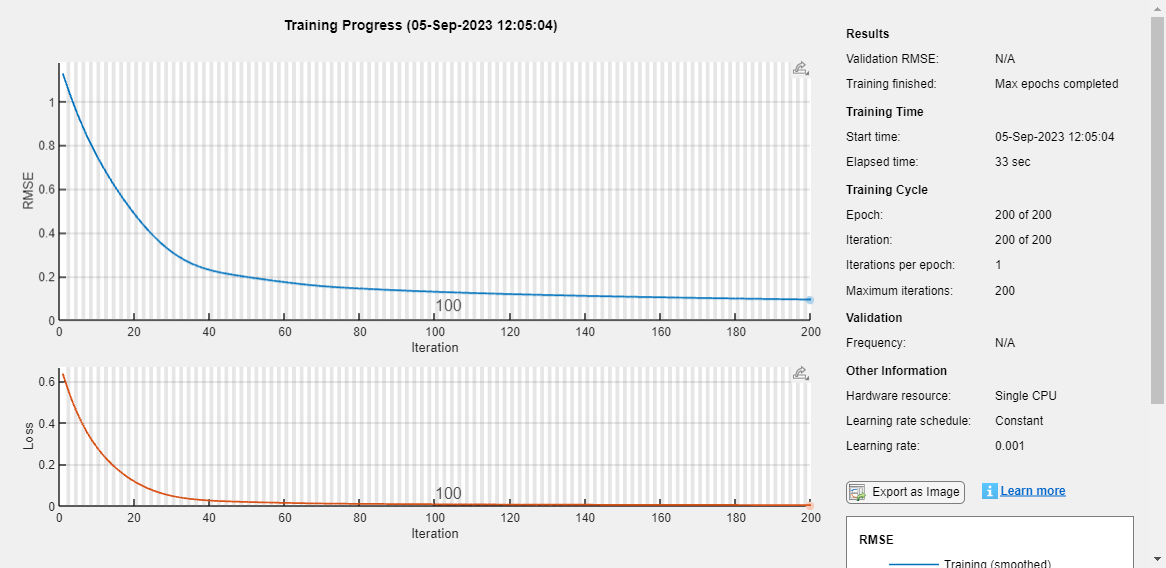

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt';

data = readtable(url);

% Input
d = table2array(data(:, end-39:end));
x_train = d(1:205, :);
x_valid = d(206:end, :);

% Measured output
meas = data.Parachor;
y_train = meas(1:205);
y_valid = meas(206:end);

train = [x_train, y_train];
valid = [x_valid, y_valid];

% Scale training and validation data
mu_train = mean(train,1);
sigma_train = std(train,0,1);

sc_train = (train-mu_train)./sigma_train;
xs_train = sc_train(:, 1:end-1);
ys_train = sc_train(:, end);

sc_valid = (valid-mu_train)./(sigma_train);
xs_valid = sc_valid(:, 1:end-1);
ys_valid = sc_valid(:, end);

% Create neural network model
layers = [ sequenceInputLayer(40)
    fullyConnectedLayer(40)
    fullyConnectedLayer(40)
    tanhLayer()
    fullyConnectedLayer(5)
    fullyConnectedLayer(1)
    regressionLayer()
    ];

% Clarify more options for the fit
options = trainingOptions('adam', ...
    MaxEpochs=200, ...
    MiniBatchSize=100, ...
    Verbose=true, ...
    Plots='training-progress',...
    InitialLearnRate=0.001);

% Train the neural network
net = trainNetwork(xs_train',ys_train',layers,options);

% Test the model on training and validation data
Y1P = predict(net, xs_train');
Y2P = predict(net, xs_valid');

% Unscale for plotting and analysis
Y1u = ys_train * sigma_train(end) + mu_train(end);
Y1Pu = Y1P * sigma_train(end) + mu_train(end);

Y2u = ys_valid * sigma_train(end) + mu_train(end);
Y2Pu = Y2P * sigma_train(end) + mu_train(end);

% Calculate MSE values

% Get MSE values

mse_nn_train = mean((p_train - Y1Pu').^2);
fprintf('Mean Squared Error (Train): %.4f\n', mse_nn_train);

Mean Squared Error (Train): 513.4955


squared_errorsnn = abs(p_train - Y1Pu');
for i=1:size(p_train)
    squared_errorsnn(i) = squared_errorsnn(i) / p_train(i); 

end
nn_error = sum(squared_errorsnn) / 205

nn_error = single
0.0268


mse_nn_val = mean((p_validate - Y2Pu').^2);
fprintf('Mean Squared Error (Valid): %.4f\n', mse_nn_val);

Mean Squared Error (Valid): 13233.1348


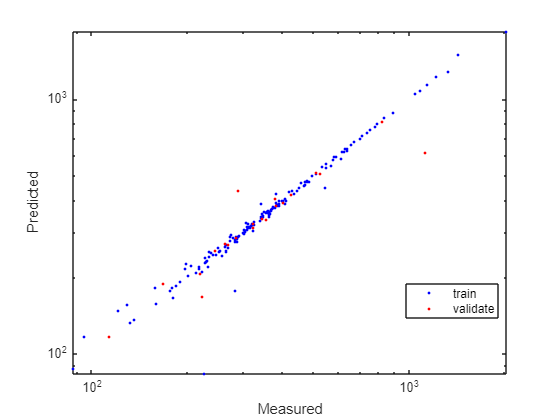


% Plot Measured vs Predicted
figure;
loglog(Y1u, Y1Pu, 'b.', 'DisplayName', 'train');
hold on;
loglog(Y2u, Y2Pu, 'r.', 'DisplayName', 'validate');
xlabel('Measured');
ylabel('Predicted');
legend('Location', 'best');

The neural network performed well with just a few outliers. Now we'll view and analyze some parameter weights of the neural network. 

net.Layers(2, 1).Weights  

ans = 40×40 single matrix
    0.2641    0.0560    0.1532   -0.2021    0.0634    0.1182   -0.1945   -0.1816    0.0258    0.1498    0.0608   -0.0914   -0.0329   -0.1930    0.1918    0.0080   -0.1321    0.2315    0.0172   -0.0049    0.0283    0.0626    0.2540   -0.2105    0.0214    0.0942   -0.2227    0.0390    0.2046    0.1806   -0.1868   -0.2639   -0.1986    0.2157    0.0139    0.1026   -0.1252    0.0910    0.1485   -0.1856
    0.0615    0.0537   -0.2271   -0.0454   -0.2034   -0.1991    0.1823   -0.2437   -0.0580    0.1566   -0.0613   -0.1569   -0.0537   -0.2568   -0.0922   -0.0029   -0.2227    0.0532   -0.1721    0.1057    0.0748    0.0470    0.0947   -0.1838    0.1260   -0.0392   -0.0081    0.1582    0.0783    0.0148   -0.1870    0.1344   -0.0815    0.0674    0.3029    0.2054   -0.0414   -0.1527    0.0714   -0.0682
    0.1652   -0.2796    0.1578   -0.2188   -0.2134    0.1035   -0.0999   -0.2288   -0.0880   -0.1823    0.2866   -0.0766    0.1061   -0.2465    0.0156    0.1847   -0.1433  

Some of the weights are negative meaning that the group is inversely related to the parachor value. To practice using constraints, we're going to assume that hypothetically all groups are positively related to the parachor value. 

## Linear Regression Model with Constraints

This linear regression model will assume that all groups are either positively related to the parachor value or not related, none will be inversely related. We'll do this by setting a lower bound of 0 for the coefficients of each variable. 

% Set the bounds
lower_bound = zeros(1,40);
upper_bound = ones(1,40)*inf;

% Create the linear model with the bounds
model = lsqlin(data_train, p_train, [],[],[],[],lower_bound, upper_bound)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


model =    45.8407
   40.8967
   34.7641
   22.4510
    0.0000
    0.0000
    0.0000
   30.5580
    8.7925
   51.1012



% Predict parachor values
p_predicted_train = mtimes(data_train, model);
p_predicted_validate = mtimes(data_validate,model);

% Get MSE values
squared_errors = (p_train-p_predicted_train).^2;
mse_lincon_train = mean(squared_errors);
fprintf("Train MSE: %.3f", mse_lincon_train)

Train MSE: 3034.738

squared_errorslr = abs(p_train - p_predicted_train);
for i=1:size(p_train)
    squared_errorslr(i) = squared_errorslr(i) / p_train(i); 

end
lr_error = sum(squared_errorslr) / 205

lr_error = 0.0724




squared_errors = (p_validate-p_predicted_validate).^2;
mse_lincon_val = mean(squared_errors);
fprintf("Validation MSE: %.3f", mse_lincon_val)

Validation MSE: 2095.759

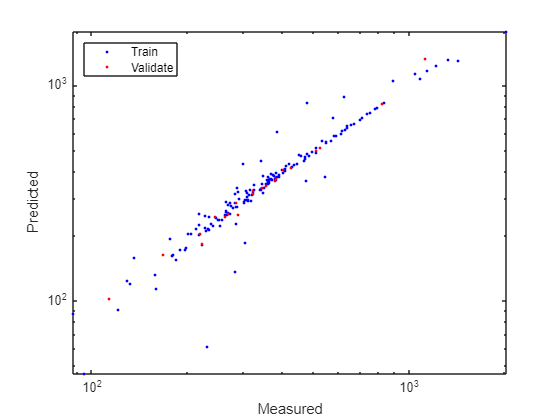


% Graph
figure;
loglog(p_train, p_predicted_train, 'b.');
hold on
loglog(p_validate, p_predicted_validate, 'r.');
hold off
xlabel('Measured');
ylabel('Predicted');
legend('Train', 'Validate', 'Location', 'northwest');

The constraint helped moved some of the outliers at the top of the graph more inline but in other areas it made the predictions less accurate. 

### Analysis of the Various Methods

We'll compare the MSE's of each method in training and validation. 

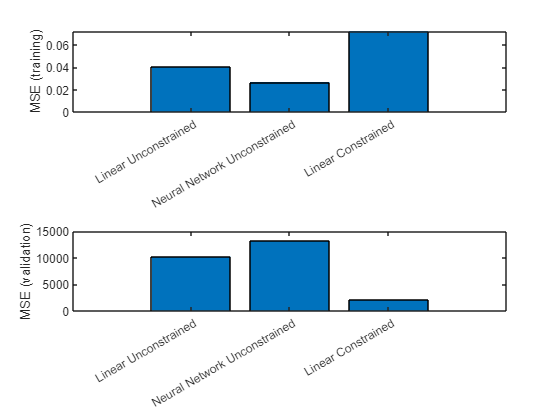

% Make bar charts to compare the MSE's
figure;

% Training MSE chart
subplot(2,1,1)
train_mse_data = [mse_lin_train nn_error lr_error];
bar(train_mse_data)
ylabel("MSE (training)");
xticklabels({'Linear Unconstrained', 'Neural Network Unconstrained', 'Linear Constrained'});

% Validation MSE chart
subplot(2,1,2)
val_mse_data = [mse_lin_val mse_nn_val mse_lincon_val];
bar(val_mse_data)
ylabel("MSE (validation)");
xticklabels({'Linear Unconstrained', 'Neural Network Unconstrained', 'Linear Constrained'});

The neural network performed better in general than the unconstrained linear model. It's likely that the linear unconstrained model overfit to the training data making it perform worse in validation. The linear constrained model performed the worst in training but then the best in validation. This is a great example of a useful constraint since it stopped the model from overfitting to the training data which helped it perform better in validation. Using scientific models to add constraints when fitting models to data can help make a better fit and avoid overfitting to training data. 